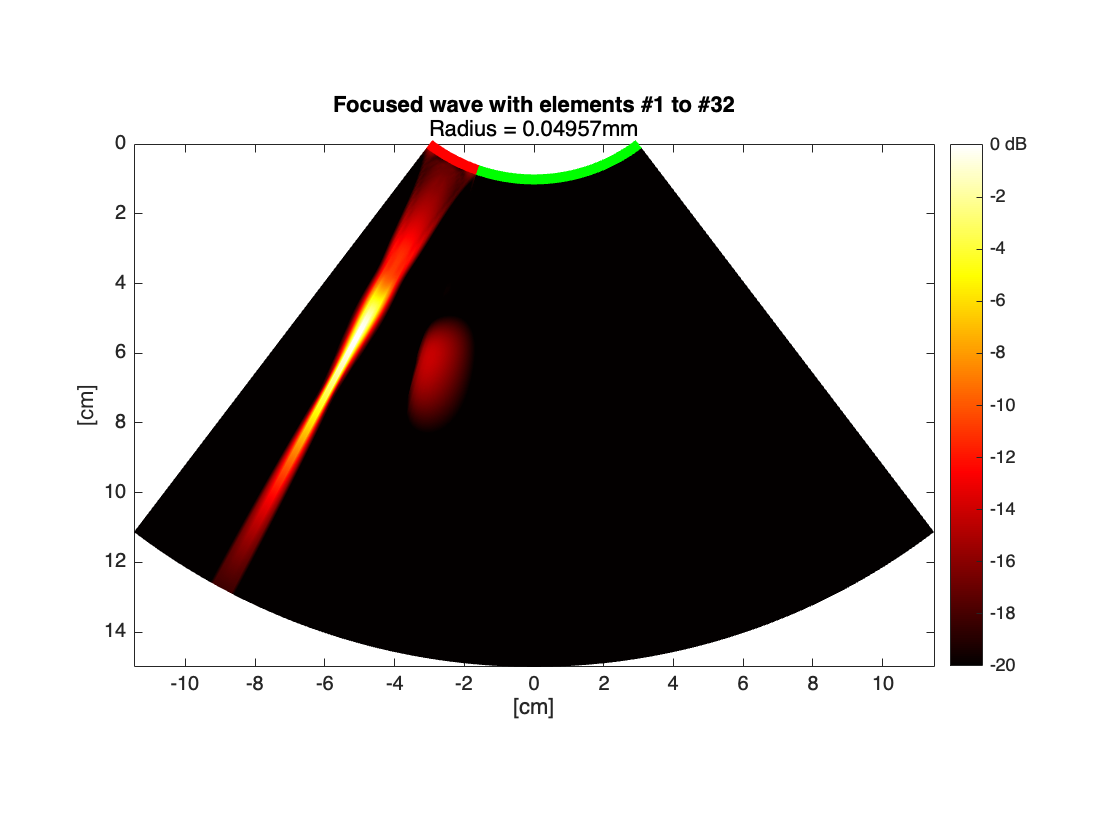

clear; clear all; clc;
% Download the properties of a 3.6-MHz 128-element 
% curved linear array in a structure param by using GETPARAM.
param = getparam('C5-2v');
freq_linear = [2.5e6, 3.57e6, 7.5e6];

% Calculating the positions of the elements (for visualization).
for i = 1:length(freq_linear )

    param = setfield(param,'fc',freq_linear (i));
    R = param.radius; % 0.0496 m
    p = param.pitch; % 5.080e-04 m
    N = param.Nelements;
    L = 2*R*sin(asin(p/2/R)*(N-1)); % chord length
    h = sqrt(R^2-L^2/4);
    th = linspace(atan2(-L/2,h),atan2(L/2,h),N);
    xe = R*sin(th);
    ze = R*cos(th)-h;
    
    % Creating a convex "sub-array" with 32 elements.
    param_suba = param;
    param_suba.Nelements = 32;
    
    % Define a focus location at xf = 0 cm, zf = 7.5 cm, 
    % relative to the sub-array
    xf = 0; zf = 7.5e-2; % focus position (in m)
    
    % Calculate the transmit time delays (in s) for the sub-array.
    txdel_suba = txdelay(xf,zf,param_suba); % in s
    
    % Obtain the transmit time delays (in s) for the (complete) array
    % when firing with elements #1 to #32
    txdel_1to32 = NaN(1,128);
    txdel_1to32(1:32) = txdel_suba;
    
    % Simulate the pressure fields by using PFIELD.
    % First define an image polar-type grid by using IMPOLGRID.
    [x,z] = impolgrid([128 128],15e-2,param);
    y = zeros(size(x));
    
    % The function PFIELD yields the root-mean-square (RMS) pressure fields.
    P_1to32 = pfield(x,y,z,txdel_1to32,param);
    
    % Display the acoustic pressure field when firing elements #1 to #32.
    pcolor(x*1e2,z*1e2,20*log10(P_1to32/max(P_1to32(:))))
    shading interp
    colormap hot
    axis equal tight ij
    caxis([-20 0]) % dynamic range = [-20,0] dB
    c = colorbar;
    c.YTickLabel{end} = '0 dB';
    xlabel('[cm]'), ylabel('[cm]')
    title('Focused wave with elements #1 to #32')
    subtitle(['Radius = ' num2str(R) 'mm'])
    
    hold on
    plot(xe*1e2,ze*1e2,'g','Linewidth',5)
    plot(xe(1:32)*1e2,ze(1:32)*1e2,'r','Linewidth',5)
    hold off

    saveas(gcf,[num2str(freq_linear (i)) '.jpg'])
end 